# **META 4**

21. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    tamanhoSinal    fimAudio    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    frequenciaDominante     par      entropia     sef      spectralSlope    fluxoMedio    planicidadeMedia    centroideMedio    larguraBandaMedia    dwtEnergyA    dwtEnergyD1    dwtEnergyD2    dwtEnergyD3    specMediaFrequencia    sp

22. Calcule, para cada dígito, a STFT, como exemplificado na Figura 5. Use diferentes parametrizações, por exemplo tamanho da janela, sobreposição, número de pontos para cálculo da FFT, etc., e identifique os parâmetros que lhe parecem mais adequados para o objetivo do trabalho. Comente as observações. Nota: utilize a função spectrogram do MATLAB (consulte a documentação associada).

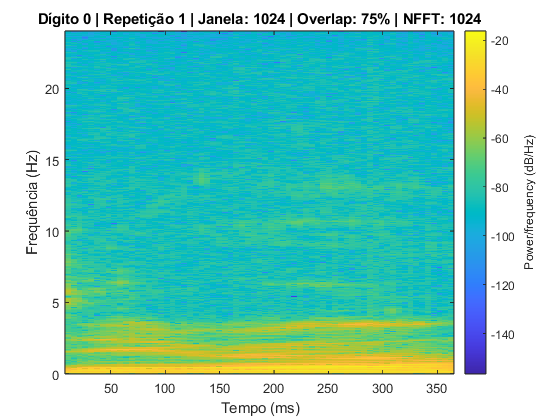

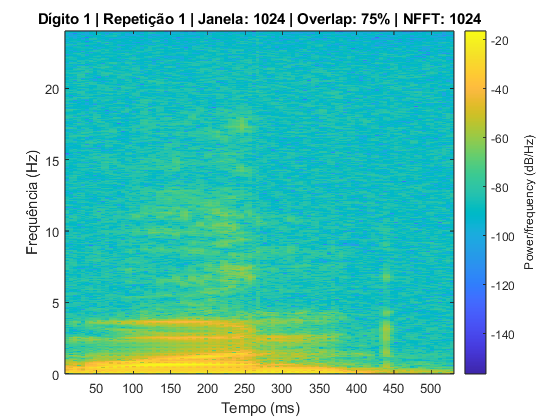

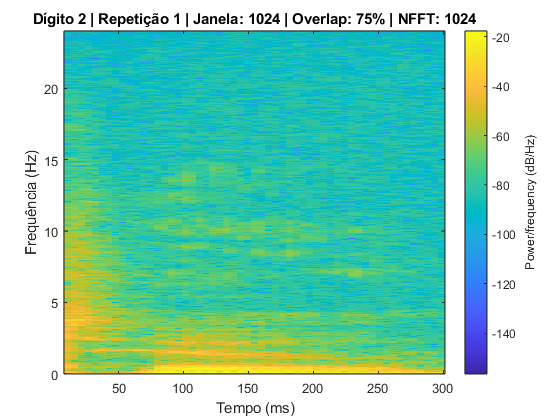

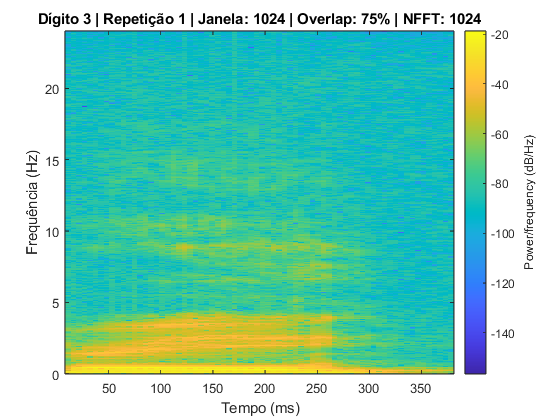

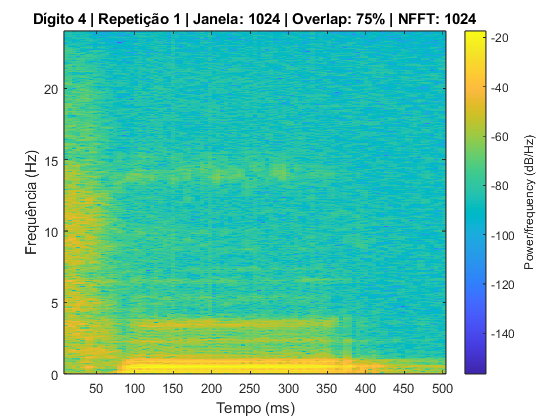

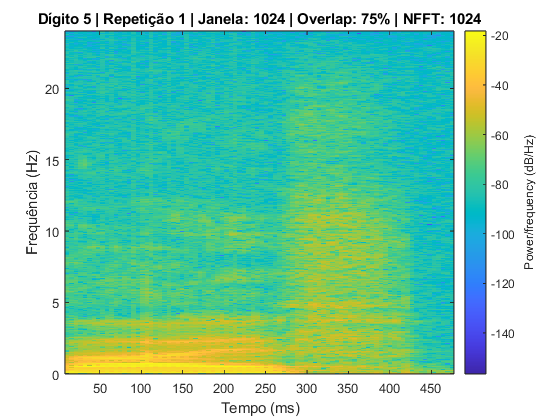

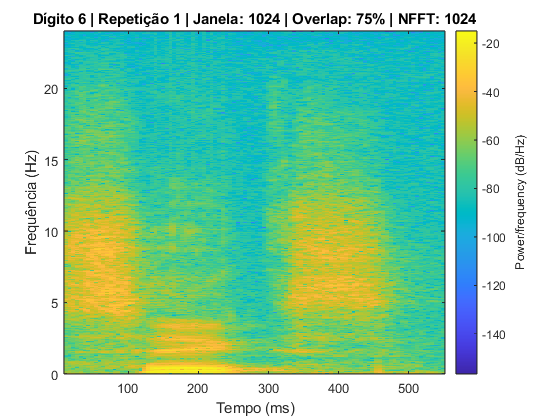

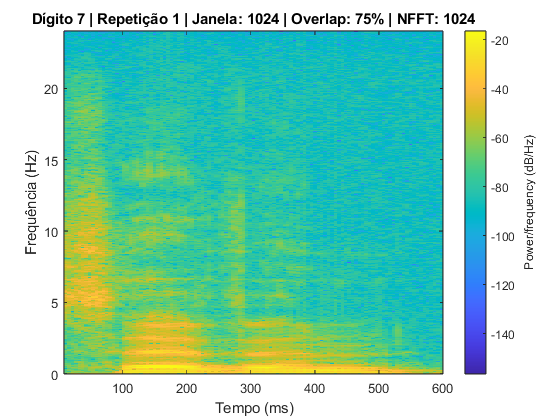

taxaAmostragem = 48000;
tamanhoJanela = 1024; 
overlap = 0.75; 
numFFT = 1024;
repeticao = 1; 

for digito = 0:9
    indice = find([dados.digito] == digito & [dados.repeticao] == repeticao, 1, 'first');
    if isempty(indice)
        continue;
    end
    sinal = dados(indice).sinal;
    fimAudio = dados(indice).fimAudio;
    sinal = sinal(1:fimAudio); % Só até ao fim do áudio real
    numOverlap = round(tamanhoJanela * overlap);
    figure;
    spectrogram(sinal, tamanhoJanela, numOverlap, numFFT, taxaAmostragem, 'yaxis');
    xlabel('Tempo (ms)');
    ylabel('Frequência (Hz)');
    title(['Dígito ', num2str(digito), ' | Repetição ', num2str(repeticao), ...
        ' | Janela: ', num2str(tamanhoJanela), ' | Overlap: ', num2str(overlap*100), '% | NFFT: ', num2str(numFFT)]);
end

23. Extraia pelo menos 5 características de tempo-frequência em diferentes janelas tempo-frequência que possam ser mais relevantes para a diferenciação dos dígitos. Deverá atualizar a sua estrutura de dados.

for i = 1:length(dados)
    sinal = dados(i).sinal;
    [s,f,t,p] = spectrogram(sinal, tamanhoJanela, numOverlap, numFFT, taxaAmostragem);
    potencia = abs(p).^2;
    mediaPotencia = mean(potencia,2); 
    
    % 1. Frequência média 
    dados(i).specMediaFrequencia = sum(f .* mediaPotencia) / sum(mediaPotencia);
    
    % 2. Fluxo Espectral (média das diferenças entre frames consecutivos)
    fluxo = sum(abs(diff(potencia, 1, 2)), 1);
    dados(i).specFluxo = mean(fluxo);
    
    % 3. Largura de banda (desvio padrão da distribuição de energia)
    dados(i).specLarguraBanda = sqrt(sum(((f - dados(i).specMediaFrequencia).^2) .* mediaPotencia) / sum(mediaPotencia));
    
    % 4. Entropia espectral
    p_norm = mediaPotencia / sum(mediaPotencia);
    dados(i).specEntropia = -sum(p_norm .* log(p_norm + eps));
    
    % 5. Energia total
    dados(i).specEnergia = sum(potencia(:));
end

24. Recorrendo à representação gráfica das características tempo-frequência extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

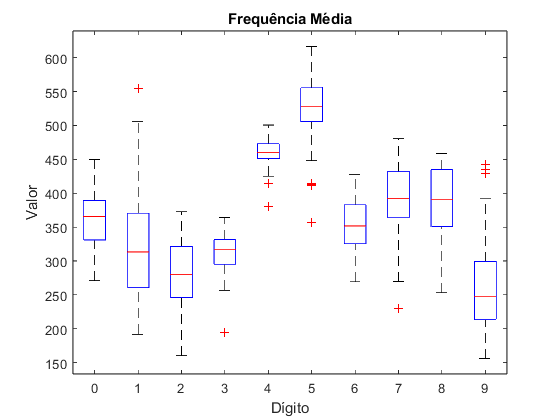

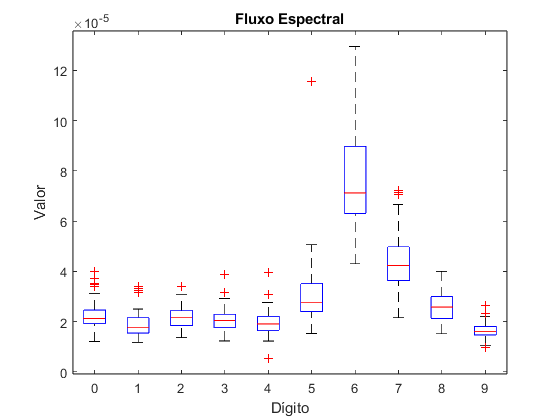

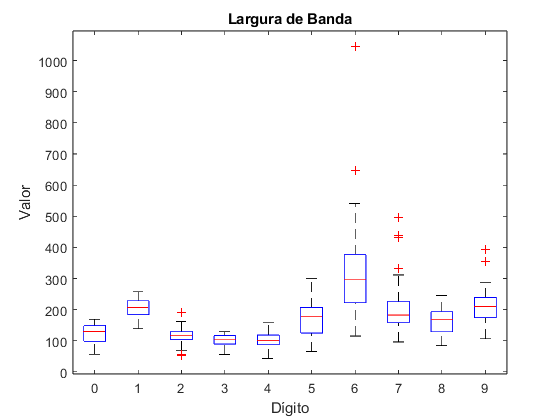

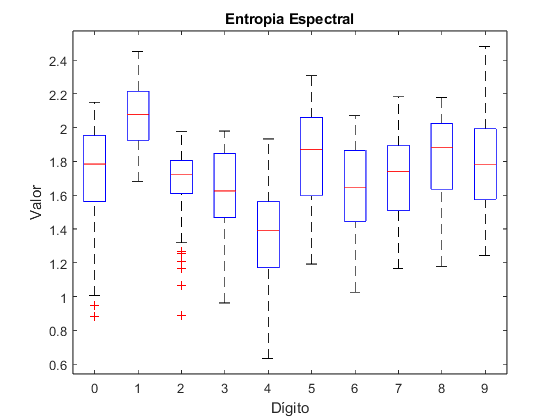

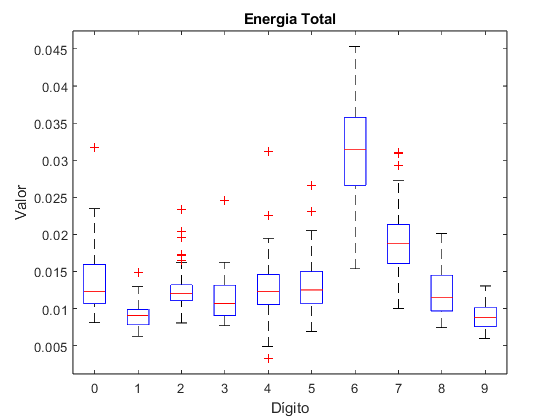

digitos = [dados.digito]';
features = [[dados.specMediaFrequencia]', [dados.specFluxo]', [dados.specLarguraBanda]', ...
            [dados.specEntropia]', [dados.specEnergia]'];

nomes_features = {'Frequência Média', 'Fluxo Espectral', ...
                 'Largura de Banda', 'Entropia Espectral', 'Energia Total'};

for i = 1:5
    figure;
    boxplot(features(:,i), digitos);
    title(nomes_features{i});
    xlabel('Dígito');
    ylabel('Valor');
end

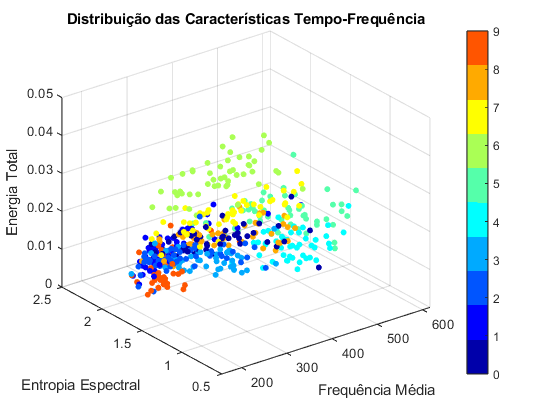


figure;
scatter3(features(:,1), features(:,4),features(:,5), 20, digitos, 'filled');  
xlabel('Frequência Média'); 
ylabel('Entropia Espectral'); 
zlabel('Energia Total');
grid on;
title('Distribuição das Características Tempo-Frequência');

colormap(jet(10));  
caxis([0 9]); 
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};

25. Aplicar a Transformada de Wavelet Discreta (DWT) para obter os coeficientes de detalhe e de aproximação, utilizando um nível de decomposição e o tipo de wavelet que considere apropriado. Obter os valores de energia a partir dos coeficientes e representar os resultados, utilizando gráficos semelhantes aos exemplificados na Figura 3. Compare e discuta os resultados obtidos com a STFT e com a DWT.

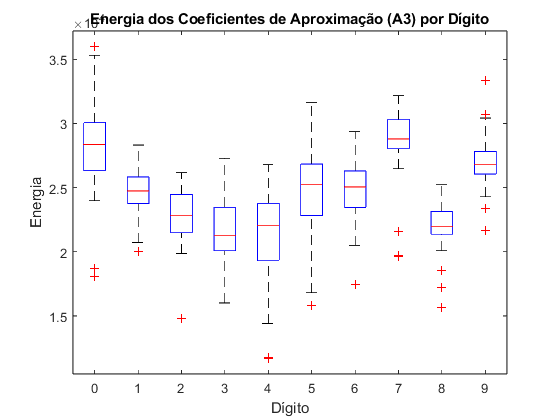

onda = 'db4'; % Escolha da wavelet (pode ser alterada)
nivel = 3;    % Nível de decomposição (ajuste conforme necessário)

% Inicializar arrays para armazenar as energias
energiesA = zeros(length(dados), 1);
energiesD1 = zeros(length(dados), 1);
energiesD2 = zeros(length(dados), 1);
energiesD3 = zeros(length(dados), 1);

for i = 1:length(dados)

    sinal = dados(i).sinal;
    [coeficientes, comprimentos] = wavedec(sinal, nivel, onda);
    
    % Coeficientes de aproximação no último nível
    cA = appcoef(coeficientes, comprimentos, onda, nivel);
    
    % Coeficientes de detalhe em cada nível
    cD1 = detcoef(coeficientes, comprimentos, 1);
    cD2 = detcoef(coeficientes, comprimentos, 2);
    cD3 = detcoef(coeficientes, comprimentos, 3);

    % Energia dos coeficientes
    energiesA(i) = sum(cA.^2);
    energiesD1(i) = sum(cD1.^2);
    energiesD2(i) = sum(cD2.^2);
    energiesD3(i) = sum(cD3.^2);

    % Armazenar na estrutura de dados
    dados(i).dwtEnergyA = energiesA(i);
    dados(i).dwtEnergyD1 = energiesD1(i);
    dados(i).dwtEnergyD2 = energiesD2(i);
    dados(i).dwtEnergyD3 = energiesD3(i);

end



% Boxplots das energias por dígito
digitos = [dados.digito]';

figure;
boxplot(energiesA, digitos);
title('Energia dos Coeficientes de Aproximação (A3) por Dígito');
xlabel('Dígito');
ylabel('Energia');

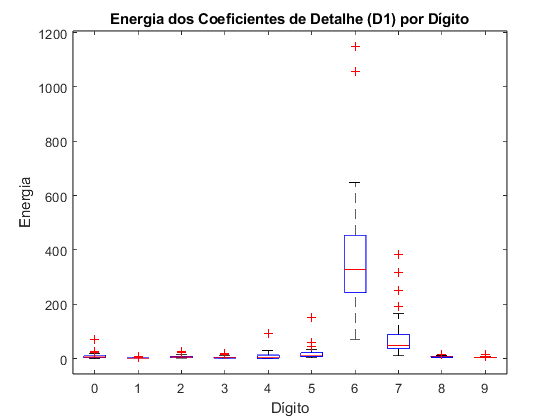


figure;
boxplot(energiesD1, digitos);
title('Energia dos Coeficientes de Detalhe (D1) por Dígito');
xlabel('Dígito');
ylabel('Energia');

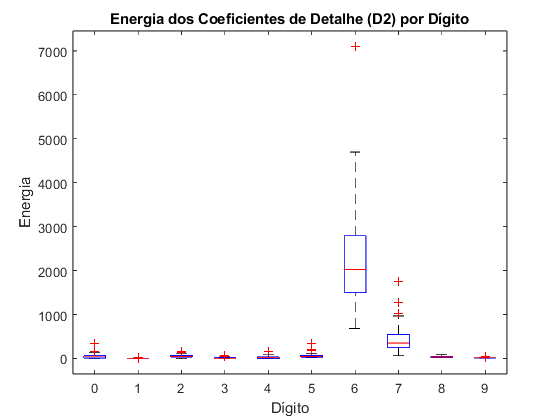


figure;
boxplot(energiesD2, digitos);
title('Energia dos Coeficientes de Detalhe (D2) por Dígito');
xlabel('Dígito');
ylabel('Energia');

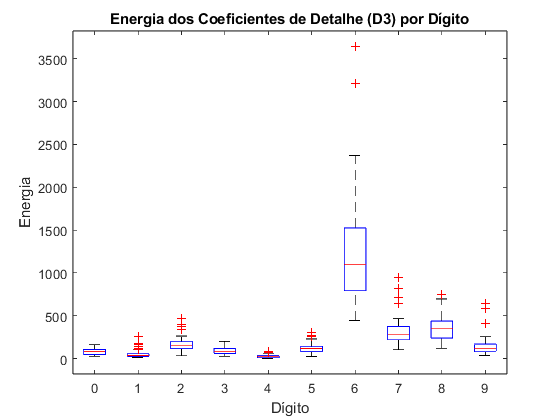


figure;
boxplot(energiesD3, digitos);
title('Energia dos Coeficientes de Detalhe (D3) por Dígito');
xlabel('Dígito');
ylabel('Energia');

26. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

%save('dados.mat', 'dados');